fprintf("PLEASE SELECT AN IMAGE\n")

PLEASE SELECT AN IMAGE


i=uigetfile('*.*');
j=imread(i)

j = 270×480×3 uint8 array
j(:,:,1) =

   207   206   205   204   204   205   206   207   204   207   210   208   204   199   198   200   205   205   199   193   190   194   200   206   192   197   208   213   212   212   213   215   212   211   211   212   216   216   217   215   212   210   217   211   219   212   217   216   208   208   200   193   195   204   207   204   203   205   207   208   206   203   204   207   203   207   211   211   206   204   206   209   208   210   213   214   214   215   217   220   219   220   219   218   218   215   216   215   214   214   214   214   215   215   217   217   218   218   218   218   216   216   218   218   219   214   211   204   199   170   109   138   209   213   216   211   204   198   196   193   188   173   162   153   160   185   189   158   172   197   182   161   167   151   110    99   157   215   224   205   216   219   209   223   226   211   205   209   209   202   213   231   232   231   230   223   214   211   220   232  

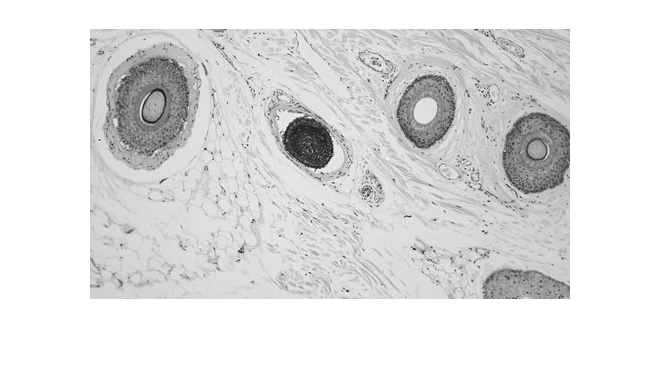

k=rgb2gray(j);
imshow(k)

[r,c]=size(k)

r = 270

c = 480

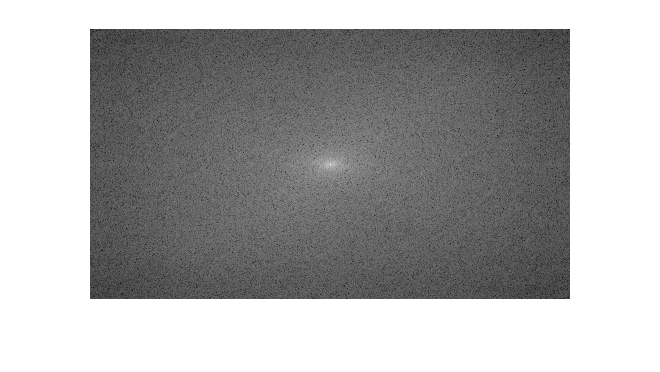

l=fft2(k);
m=fftshift(l);
n=abs(m);
o=log(1+n);
imshow(o,[]);

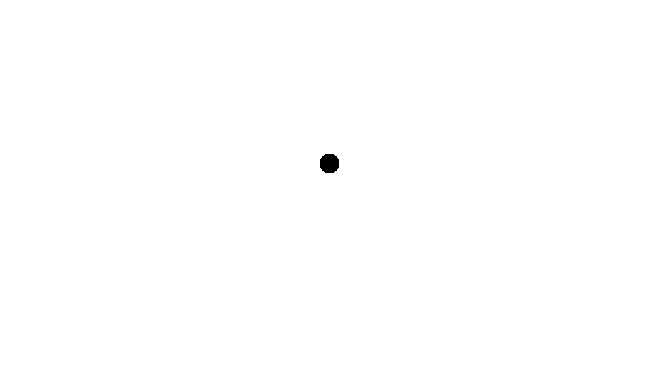

Z=zeros(r,c);
for R=1:r
    for C=1:c
        if (R-r/2)^2+(C-c/2)^2 <= 10^2
                Z(R,C)=1;            
        end
    end
end
imshow(Z)

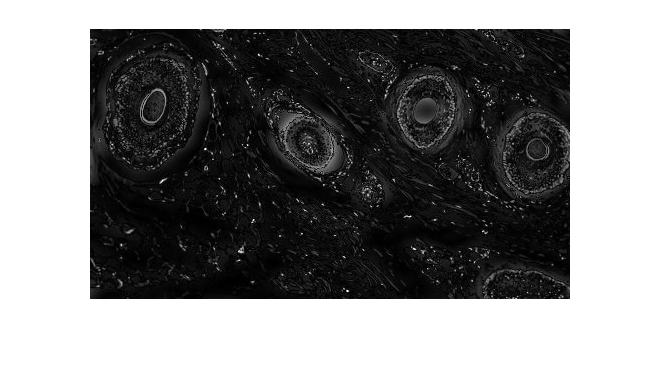

new=m.*Z;
new1=fftshift(new);
new2=ifft2(new1);
imshow(abs(new2),[]);

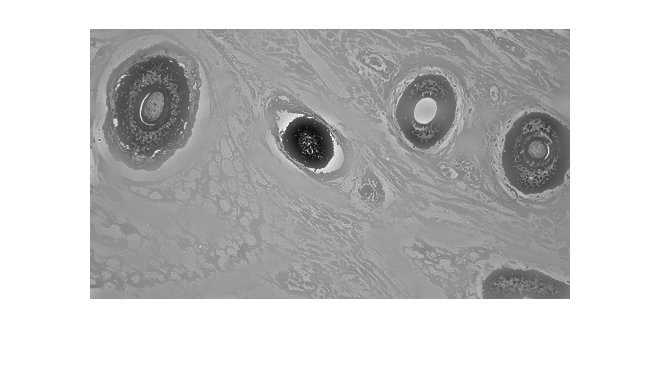

edge=abs(new2);
sharp=double(k)+edge;
imshow(sharp,[]);

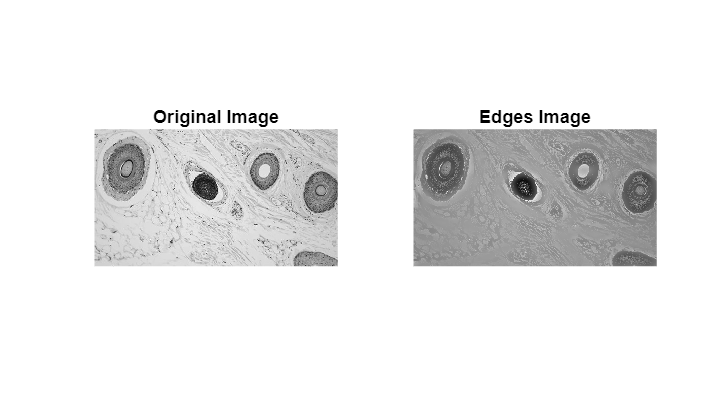

subplot(1,2,2); imshow(sharp,[]); title('Edges Image');
subplot(1,2,1); imshow(k,[]); title('Original Image');